clear all, close all, clc

## HW03-2

Here, the energy of the emitting alpha particle are-

E1 = 6.82;      % MeV, 10%
E2 = 4.3;       % MeV, 90%

Now, a A classical $\left(\alpha ,\ n\right)$reaction is


$${}^4_2{\alpha }+{}^9_4{Be}\to {}^{12}_6C+{}^1_0n$$


Given, the activity of the mixture-

A = 40e9;        % Bq, dps
M_1 = 0.1*A;     % Bq, for 6.82 MeV
M_2 = 0.9*A;     % Bq, for 4.30 MeV

Now, we get following equation from the textbook for neutron yield-


$$Y_n ={\left\{\begin{array}{c}
0.115E_{\alpha }^{3.82} \ \\
E_{\alpha }^{2.64} 
\end{array}\begin{array}{c}
3.5\le E_{\alpha } \le 6.5\ MeV\\
6.5\le E_{\alpha } \le 10\ MeV
\end{array}\ \right)}$$


So, the neutron yield in million $\alpha \;$

Y1 = E1^2.64            % #/M-alf

Y1 = 158.9245

Y2 = 0.115*E2^3.82      % #/M-alf

Y2 = 30.2376

Let's convert them for 1-$\alpha \;$

Y1 = Y1 /1e6;           % #/alf
Y2 = Y2 /1e6;           % #/alf

Now, let's find the neutron numbers, doing the activity split

n1 = Y1 *M_1             % n/s, for 6.82 MeV-alf

n1 = 6.3570e+05

n2 = Y2 *M_2             % n/s, for 4.30 MeV-alf

n2 = 1.0886e+06

So, total number of neutrons

n = n1 + n2

n = 1.7243e+06

    (Ans)

So, if we sketch the energy spectrum, we will get something like this-

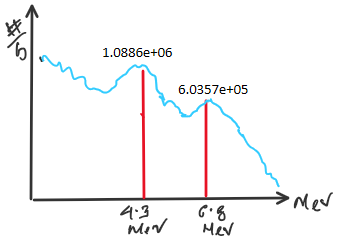

## HW03-3

Given,

t_o = 30e3;             % reactor operating time; hr
t_o = t_o *60^2         % operating time; s

t_o = 108000000

t_s =  1;               % reactor shutdown time; y
t_s =  t_s *60^2*24*365 % s

t_s = 31536000

P_ow = 20e6;            % power; W, J/s
    J_MeV = 1.6e-13;    % J/MeV
Cv = 200;               % energy release /fsn; MeV/fsn
Cv = Cv*J_MeV;          % J/fsn
P_o = P_ow /Cv          % fsn/s 

P_o = 6.2500e+17

Let's use the following equation from the book, eqn 4.16


$$\Gamma {\left(t_o ,t_s \right)}=P_o \sum_{i=1}^{N_j } \frac{\alpha_{ij} }{\lambda_{ij} }e^{-\lambda_{ij} t_s } \left(1-e^{-\lambda_{ij} t_o } \right)$$


Now, from the textbook Table G.3 of Appendix G, we get the following for $\alpha \;$and $\lambda \;$constants for $\beta \;$and $\gamma \;$emission

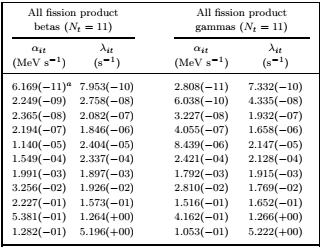

Now, from the above table, let's tabluate the followings-

Here's the $\alpha \;$ and $\lambda \;$values for $\beta \;$emission

al_bt = [6.169E-11, 2.249E-9 , 2.365E-8, 2.194E-7, 1.140E-5, 1.549E-4, 1.991E-3, 3.256E-2, 2.227E-1, 5.381E-1, 1.282E-1];
lm_bt = [7.953E-10, 2.758E-8 , 2.082E-7, 1.846E-6, 2.404E-5, 2.337E-4, 1.897E-3, 1.926E-2, 1.573E-1, 1.264E0,  5.196E0];

And, the $\alpha \;$ and $\lambda \;$values for $\gamma \;$emission

al_gm = [2.808E-11, 6.038E-10, 3.227E-8, 4.055E-7, 8.439E-6, 2.421E-4, 1.792E-3, 2.810E-2, 1.516E-1, 4.162E-1, 1.053E-1];
lm_gm = [7.332E-10, 4.335E-8,  1.932E-7, 1.658E-6, 2.147E-5, 2.128E-4, 1.915E-3, 1.769E-2, 1.652E-1, 1.266E0,  5.222E0];

 So, let's vectorize the following expression-


$$\textrm{Ex}=\frac{\alpha_{ij} }{\lambda_{ij} }e^{-\lambda_{ij} t_s } \left(1-e^{-\lambda_{ij} t_o } \right)$$


beta = (al_bt./lm_bt).*exp(-lm_bt.*t_s).*(1 - exp(-lm_bt.*t_o));
gamma = (al_gm./lm_gm).*exp(-lm_gm.*t_s).*(1 - exp(-lm_gm.*t_o));

And then, sum the values up in the vector-

sum_bt = sum(beta);
sum_gm = sum(gamma);

Now, to finalize the energy calculation, we do-

P_bt = P_o*sum_bt       % energy emission in beta rate, MeV/s

P_bt = 2.4262e+16

P_gm = P_o*sum_gm       % energy emission in gama rate, MeV/s

P_gm = 4.2145e+15

    (Ans)

## HW03-4

Here, subscript 1 is used for Ca-47, and 2 is used for Ca-49

Given,

m = 2;                  % sample mass; g
M_1 = 47;               % molar mass; g/mol
M_2 = 49;

Now, from Textboo, Appendix C, Table C2

a1 = 0.0033*1e-2;           % istotopic abundance 
a2 = 0.185*1e-2;              
Na = 6.02e23;               % Avogadro's number

So, we have-


$$N=\frac{m}{M}\;N_a \;\;a$$


N_1 = m/M_1 *Na *a1         % No. of isotpes in the sample

N_1 = 8.4536e+17

N_2 = m/M_2 *Na *a2         % 

N_2 = 4.5457e+19

Now, let's calculate what fraction of those isotopes being activiated because of neutron irradiation. We have-


$$N_u =N\;\sigma_{\gamma \;} \;\phi_{\textrm{nu}} \;\Delta t\;$$


phi = 1e10;                 % nu' flux; cm^-2.s^-1
dt = 30;                    % irradiation time; s 

sg_1 = 0.74;                % activation CS, barns
sg_1 = sg_1*1e-24;          % cm^-2
Nu_1 = N_1 *sg_1*phi*dt     % no. of activated nuclides

Nu_1 = 1.8767e+05

And,

sg_2 = 1.09;                % barns
sg_2 = sg_2*1e-24;          % cm^-2
Nu_2 = N_2 *sg_2*phi*dt     % no. of activated nuclides

Nu_2 = 1.4864e+07

Now, let's calculate the activity of daughter nuclide

From textbook, Appendix C, Table C2

T_h_1 = 4.536 *60^2*24;     % half life; s
lm_1 = log(2)/T_h_1         % decay const.; s^-1

lm_1 = 1.7686e-06


T_h_2 = 8.72 *60;           % half life, s
lm_2 = log(2)/T_h_2         % decay const., s^-1

lm_2 = 0.0013

Now, let's find the activity after t = 120 s, with following equations-


$$A_o =N_u \lambda \;$$



$$A\left(t\right)=A_0 \;e^{-\lambda \;t}$$


t = 2*60;                   % total time; s 
A0_1 = Nu_1 *lm_1           % initial activity of daughter; Bq, dps

A0_1 = 0.3319

A_t_1 = A0_1 *exp(-lm_1*t)  % activity after t; Bq

A_t_1 = 0.3319

And,

A0_2 = Nu_2 *lm_2           % initial activity of daughter, Bq, dps

A0_2 = 1.9693e+04

A_t_2 = A0_2 *exp(-lm_2*t)  % activity after t, Bq

A_t_2 = 1.6798e+04

Now, we know, the source strength is-


$$S{\left(E\right)}=\sum \gamma_i A_i$$


From textbook, Appendix H, Table H1, we get the g-energy in MeV-

gm_1 = 0.4892;          % photon energy, MeV, Ca-47 
gm_2 = 3.0844;          % MeV, Ca-49

So, we have,

S_E = gm_1 *A_t_1 + gm_2 *A_t_2,     % source strength, MeV/s

S_E = 5.1813e+04

Now, let's find out the photon flux density with following equation

r = 1e2;                    % sphere rad', cm
A = 4*pi*r^2                % sphere area, cm^2

A = 1.2566e+05

phi_p = S_E /A              % photon flux; MeV/cm^-2.s^-1

phi_p = 0.4123

(Ans)